# Copenhagen Needle EMG Analysis

Read needle EMG data, for biceps brachii muscle (gain of 500, HPF 2Hz, LPF 10Hz)

%preprocessed needle EMG data from University of Copenhagen dataset
fileID = fopen('N2001C01BB52.bin'); %healthy biceps brachii
nemg1 = fread(fileID)

nemg1 =     29
     0
    13
    15
   224
    14
     4
    15
   247
    14


nemg1_header = fileread('N2001C01BB51.hea')

nemg1_header =     'N2001C01BB51 1 23437.5 262124
     N2001C01BB51.bin 16+20 13.1070/uV
     #gender: M
     #age: 29
     #diagnosis: healty controls
     #duration: 
     #muscle: Biceps brachii (long head)
     #side: Right
     #protocol: steady isometric contraction
     #level: low
     #electrode: concentric needle
     #high-pass filter: 2 Hz
     #low-pass filter: 10 kHz
     #gain: 500
     #contributor: Miki Nikolic, Dept Clinical Neurophysiology, Rigshospital, Copenhagen
     #date: 08/2001
     #indentifier: C:\Documents and Settings\Zhelyazko Tumbev\Desktop\New Folder (4)\Recordings\1ch\36744\5\EMGDAT\1.bin
     #contact: mn@e-med.dk
     '


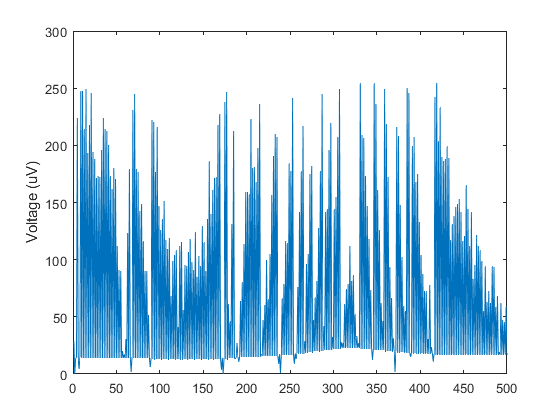

figure
plot(nemg1); ylabel('Voltage (uV)')
xlim([0 500])

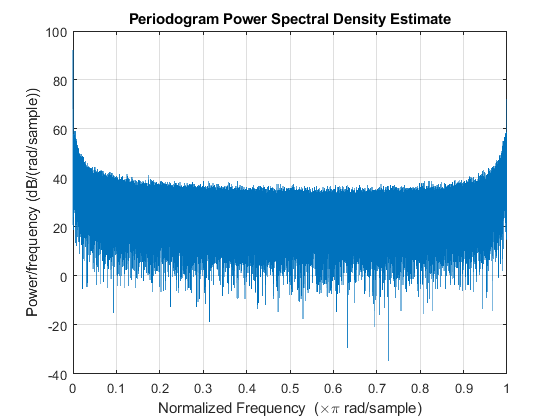

periodogram(nemg1)

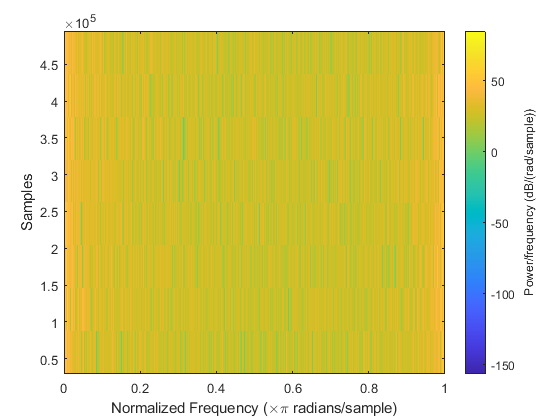

spectrogram(nemg1)

Note: From visual inspection, there appears to be a DC offset of rectified EMG amplitude values.

Setup

%signal acquisition parameters
L = length(nemg1)

L = 524288

t = 0:L-1;
Ts = mean(diff(t));                                 % Sampling Time
Fs = 1/Ts;                                          % Sampling Frequency
Fn = Fs/2;                                          % Nyquist frequency
fftSignal = fft(nemg1);
fftSignal = fftshift(fftSignal);
f = Fs/2*linspace(-1,1,Fs);

Fcp_low=0.5;  %lower cutoff frequency
Fcp_high=500;  %higher cutoff frequency
%Fsp = 10000;
[z,p,k]=butter(8,[Fcp_low Fcp_high]/(Fsp/2),'bandpass');
[sos,g]=zp2sos(z,p,k);
%fvtool(sos,'Analysis','freq')
sEMG=filtfilt(sos,g,RF_Contract(:,1));

%some code to plot the FFT
Yy = fft(nemg1);
Pot = Yy .* conj(Yy) / L;
size(Pot)

ans =       524288           1


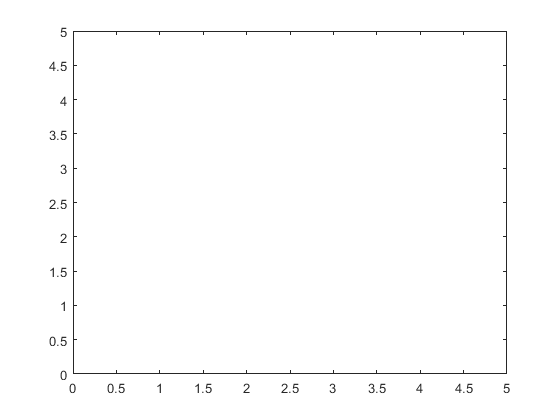

Freq = (Fs / L *(1:L))';
figure
plot(Freq(1:round(L/2)) , Pot(1:round(L/2)) );
xlim([0 5]); ylim([0 5])

Power Spectral Density of needle EMG data

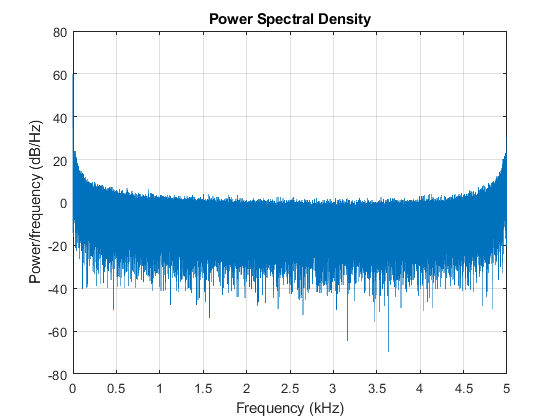

nfft = 2^nextpow2(length(nemg1));
Pxx = abs(fft(nemg1,nfft)).^2/length(nemg1)/Fs;
Hpsd = dspdata.psd(Pxx(1:length(Pxx)/2),'Fs',Fs);
figure
plot(Hpsd)

Feature Extraction

features_p1 = rawFeatures(nemg1);
writeFeaturesToFile([0], features_p1, 'copenhagen_features.txt', 'tab')